# SVM: non-linearly vs lineary separable sets

*© *Copyright 2022 The MathWorks, Inc

## Random dataset of points non linearly separable in $R^2$

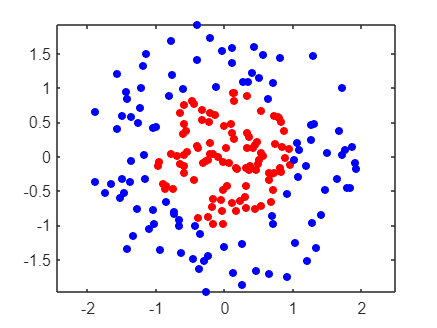

r = sqrt(rand(100 ,1));                         % random radius
t = 2*pi*rand(100 ,1);                          % random angle
data1 = [r.* cos(t), r.* sin(t)];               % points of class -1 (RED)

r2 = sqrt(3*rand(100 ,1) +1);                   % random radius for blue ring
t2 = 2* pi*rand (100,1);                        % random angle for blue ring
data2 = [r2 .* cos(t2), r2 .* sin(t2)];         % points of class +1 ( BLUE )

data3  = [data1; data2];                        % merge data together
theclass = ones(200,1);                         % assign class +1
theclass(1:100) = -1;                           % assign class -1

figure
plot(data1(:,1), data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1), data2(:,2),'b.','MarkerSize',15)
axis equal
hold off

## Run Support Vector Classification

sc = 1                % Kernel scale

sc = 1

box = Inf;                                      % BoxConstraint (Inf means hard margin classification)
mySVM = fitcsvm (data3, theclass , ClassNames =[ -1 ,1] , ...
                         KernelFunction ='rbf', KernelScale = sc, BoxConstraint = box);

## Identify Support Vectors

alpha = mySVM.Alpha                   % returns just alpha non null for support vectors

alpha =    25.4173
   11.5720
   47.4000
   41.6031
  228.9145
   76.8257
    8.1467
   17.0752
    7.2686
   31.4922


supportVectors = data3(mySVM.IsSupportVector , :)

supportVectors =    -0.5875    0.7624
    0.8000    0.5706
    0.1462    0.9325
   -0.8682   -0.4607
    0.9532   -0.1084
    0.9490    0.1231
   -0.3827   -0.8898
   -0.9924    0.4389
    0.7018   -0.8622
    0.6310    0.8481


## Predict scores over a grid

% Predict scores over a regular meshgrid to visualize boundary
[x1Grid , x2Grid] = meshgrid(min(data3(:,1)):0.02: max(data3(:,1)) ,...
                               min(data3(:,2)):0.02: max(data3(:,2)));
xGrid = [x1Grid(:) , x2Grid(:)];
[~, scores] = predict(mySVM, xGrid);
boundary = reshape(scores(:,2),size(x1Grid));

## Plot the data and the decision boundary

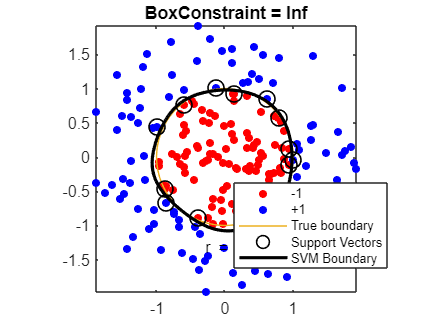

figure;
gscatter(data3(:,1),data3(:,2),theclass,'rb','.');
hold on
ezpolar(@(x) 1);
plot(supportVectors(:,1),supportVectors(:,2),'ko', 'MarkerSize', 10, 'LineWidth',1);
contour(x1Grid,x2Grid,boundary,[0 0],'k', 'LineWidth',2);

legend({'-1','+1', 'True boundary','Support Vectors','SVM Boundary'}, FontSize=8);
title("BoxConstraint = "+box )
axis equal
hold off